# **기계제어공학부 기전융합종합설계 **

#### **Patient-Friendly Falling Suspicion Alarm System Based on 3D Bounding Box on 3D LiDAR Point Cloud**

Name:        Hong Se Hyun

Date:          2022.12.02.

# **1. Add Path/Library**

**Start Project**

clc;     clear all;     close all

addpath(genpath('config'))
addpath(genpath('eval'))
addpath(genpath('models'))
addpath(genpath('utils'))

warning ('off','all');

# **2-1.   Load Train Data**

**Get ground truth label information.**

[matFiles, numFiles, mydata] = DataProcess_LoadData('traindata');

mydata_path = "../data/traindata/labeling_NTH214_1025_2030_JIHYUNBIN.mat"

mydata_path = "../data/traindata/labeling_NTH214_1025_2045_HANKWANGYONG.mat"

mydata_path = "../data/traindata/labeling_NTH214_1025_2115_ANCHANGMIN.mat"

mydata_path = "../data/traindata/labeling_NTH214_1025_2120_LEEHAEUN.mat"

mydata_path = "../data/traindata/labeling_NTH214_1028_1945_HUDABIN.mat"

mydata_path = "../data/traindata/labeling_NTH214_1028_2000_KIMHAEUN.mat"

mydata_path = "../data/traindata/labeling_NTH214_1028_2045_HONGSEHYUN.mat"

mydata_path = "../data/traindata/labeling_NTH214_1028_2100_YANGJIWOO.mat"

mydata_path = "../data/traindata/labeling_NTH214_1028_2115_CHOIYOONSEOK.mat"

mydata_path = "../data/traindata/labeling_NTH214_1028_2130_ANGYEONHEAL.mat"

# **2-2.   Data Pre-processing**

Get bounding boxes coordinate values

**10  frame = 1  second**

'pcap File to pcd File' Processed Frames = **0100~1300 **Frames

**→** Number of frames in pcd file format = **1201** **(=0100~1300)**

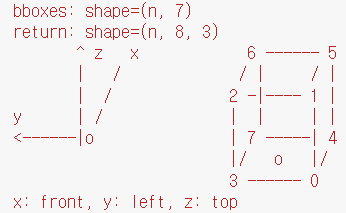

**Get names & Setting Base Variables**

mode = 5;

train_frame_info = DataProcess_DefineTrainFrames(numFiles, matFiles, mode)

train_frame_info = 다음 필드를 포함한 1×10 struct 배열:
    name
    stand
    sit
    lying_1
    lying_2
    lying_3


**Get Labeled Frames**

LABEL_stand   = {};
LABEL_sit     = {};
LABEL_lying_1 = {};
LABEL_lying_2 = {};
LABEL_lying_3 = {};

for itr = 1 : numFiles
    [TMP_LABEL_stand, TMP_LABEL_sit, TMP_LABEL_lying_1, TMP_LABEL_lying_2, TMP_LABEL_lying_3] = DataProcess_GetLabel_5(mydata{itr,1}, train_frame_info(itr).stand, train_frame_info(itr).sit, train_frame_info(itr).lying_1, train_frame_info(itr).lying_2, train_frame_info(itr).lying_3);
    
    LABEL_stand   = [LABEL_stand   ; TMP_LABEL_stand];
    LABEL_sit     = [LABEL_sit     ; TMP_LABEL_sit];
    LABEL_lying_1 = [LABEL_lying_1 ; TMP_LABEL_lying_1];
    LABEL_lying_2 = [LABEL_lying_2 ; TMP_LABEL_lying_2];
    LABEL_lying_3 = [LABEL_lying_3 ; TMP_LABEL_lying_3];
end

**Check missing and outliers**

[no_stand_label_idx,   double_stand_label_idx,   num_of_standing] = DataProcess_DataCheck(LABEL_stand);
[no_sit_label_idx,     double_sit_label_idx,     num_of_sitting] = DataProcess_DataCheck(LABEL_sit);
[no_lying_1_label_idx, double_lying_1_label_idx, num_of_lying_1] = DataProcess_DataCheck(LABEL_lying_1);
[no_lying_2_label_idx, double_lying_2_label_idx, num_of_lying_2] = DataProcess_DataCheck(LABEL_lying_2);
[no_lying_3_label_idx, double_lying_3_label_idx, num_of_lying_3] = DataProcess_DataCheck(LABEL_lying_3);

# **2-3.   Feature Extraction**

Get bounding boxes' features.

### **Features**

**Feature(1)** : x, y축의 길이의 비율

**Feature(2) **: y, z축의 길이의 비율

**Feature(3) **: z, x축의 길이의 비율 

**Feature(4) **: 3D Bbox에 대한 대각선과 x, y평면이 이루는 각도

**Get Bbox Coordinates**

stand_bboxes_coordinates   = DataProcess_BboxesExtraction(num_of_standing, LABEL_stand);
sit_bboxes_coordinates     = DataProcess_BboxesExtraction(num_of_sitting,  LABEL_sit);
lying_1_bboxes_coordinates = DataProcess_BboxesExtraction(num_of_lying_1,  LABEL_lying_1);
lying_2_bboxes_coordinates = DataProcess_BboxesExtraction(num_of_lying_2,  LABEL_lying_2);
lying_3_bboxes_coordinates = DataProcess_BboxesExtraction(num_of_lying_3,  LABEL_lying_3);

**Feature Extraction**

stand_feature_table   = DataProcess_FeatureExtraction(stand_bboxes_coordinates);
sit_feature_table     = DataProcess_FeatureExtraction(sit_bboxes_coordinates);
lying_1_feature_table = DataProcess_FeatureExtraction(lying_1_bboxes_coordinates);
lying_2_feature_table = DataProcess_FeatureExtraction(lying_2_bboxes_coordinates);
lying_3_feature_table = DataProcess_FeatureExtraction(lying_3_bboxes_coordinates);

# **2-4.   Data Post-processing**

**Add ground truth label to feature table**

stand_feature_label_table   = DataProcess_AddLabel(stand_feature_table,   'stand & walk');
sit_feature_label_table     = DataProcess_AddLabel(sit_feature_table,     'sit');
lying_1_feature_label_table = DataProcess_AddLabel(lying_1_feature_table, 'lying-Bed');
lying_2_feature_label_table = DataProcess_AddLabel(lying_2_feature_table, 'lying-Floor-Vertical');
lying_3_feature_label_table = DataProcess_AddLabel(lying_3_feature_table, 'lying-Floor-Horizontal');

**Define train data table (this table goes to ML)**

column_size = size(stand_feature_label_table, 2);

TrainData_Table       = [stand_feature_label_table(:,1:column_size-1) ; sit_feature_label_table(:,1:column_size-1) ; lying_1_feature_label_table(:,1:column_size-1) ; lying_2_feature_label_table(:,1:column_size-1) ; lying_3_feature_label_table(:,1:column_size-1)]

TrainData_Table = 10000×4 table
    length_ratio_xy    length_ratio_yz    length_ratio_zx    angle_diagonal_line
    _______________    _______________    _______________    ___________________

        0.71343            0.52473            2.6713               57.195       
        0.72334            0.50933            2.7143               57.846       
        0.73347            0.49451             2.757               58.481       
        0.74381            0.48023            2.7995               59.099       
        0.75438            0.46648            2.8417               59.701       
        0.78375            0.45662            2.7942                59.88       
        0.81447            0.44675            2.7483                60.05       
        0.84664            0.43686            2.7037               60.213       
        0.88035            0.42695            2.6605               60.367       
        0.84088            0.44329            2.6827               59.921   

TrainData_Label_Table = [stand_feature_label_table(:,column_size) ; sit_feature_label_table(:,column_size) ; lying_1_feature_label_table(:,column_size) ; lying_2_feature_label_table(:,column_size) ; lying_3_feature_label_table(:,column_size)]

TrainData_Label_Table = 10000×1 table
        label     
    ______________

    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"


**Data Description**

data_description = summary(TrainData_Table);

tab_1 = table2array(TrainData_Table(:,1));
tab_2 = table2array(TrainData_Table(:,2));
tab_3 = table2array(TrainData_Table(:,3));
tab_4 = table2array(TrainData_Table(:,4));

var_1 = var(tab_1)

var_1 = 0.8114

var_2 = var(tab_2)

var_2 = 0.3508

var_3 = var(tab_3)

var_3 = 0.7565

var_4 = var(tab_4)

var_4 = 279.7975

# **2-5.   Data Normalizaiton**

**method(1)**

Apply Data Normalization.

TrainData_Table = normalize(TrainData_Table)

TrainData_Table = 10000×4 table
    length_ratio_xy    length_ratio_yz    length_ratio_zx    angle_diagonal_line
    _______________    _______________    _______________    ___________________

        -0.3795            -1.1723            1.3185               1.2875       
       -0.36849            -1.1983             1.368               1.3264       
       -0.35725            -1.2233            1.4171               1.3644       
       -0.34577            -1.2474            1.4659               1.4013       
       -0.33404            -1.2707            1.5144               1.4373       
       -0.30143            -1.2873            1.4599                1.448       
       -0.26733             -1.304             1.407               1.4582       
       -0.23162            -1.3207            1.3558               1.4679       
       -0.19419            -1.3374            1.3061               1.4772       
       -0.23801            -1.3098            1.3316               1.4505   

data_description_norm = summary(TrainData_Table);

tab_norm_1 = table2array(TrainData_Table(:,1));
tab_norm_2 = table2array(TrainData_Table(:,2));
tab_norm_3 = table2array(TrainData_Table(:,3));
tab_norm_4 = table2array(TrainData_Table(:,4));

var_norm_1 = var(tab_norm_1)

var_norm_1 = 1.0000

var_norm_2 = var(tab_norm_2)

var_norm_2 = 1.0000

var_norm_3 = var(tab_norm_3)

var_norm_3 = 1.0000

var_norm_4 = var(tab_norm_4)

var_norm_4 = 1.0000

**method(2)**

Change Data Size by Apply Degree to Radian.

% TrainData_array      = table2array(TrainData_Table);
% TrainData_array(:,4) = TrainData_array(:,4)*pi/180;
% FeatureColumnIndex   = ["length_ratio_xy", "length_ratio_yz", "length_ratio_zx", "angle_diagonal_line"];
% TrainData_Table      = array2table(TrainData_array, 'VariableNames',string(FeatureColumnIndex))

# **2-6.   Supervise Learning**

Train and Evaluate.

**ML - KNN**

Knn_Train_Loss = 0.0400

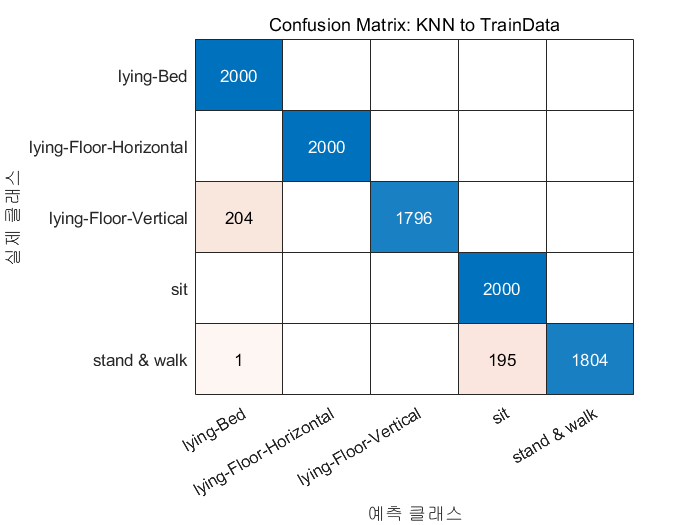

[Knn_Mdl, Knn_Train_Loss, ~] = ML_KnnTrain(TrainData_Table, TrainData_Label_Table, 2);

**ML - SVM**

SVM_Train_Loss = 0.2340

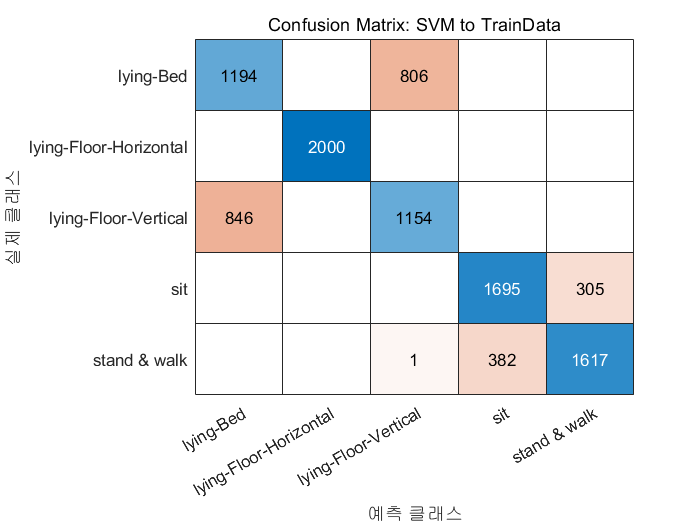

[SVM_Mdl, SVM_Train_Loss, ~] = ML_SVMTrain(TrainData_Table, TrainData_Label_Table);

**ML - TREE**

Tree_Train_Loss = 0.0198

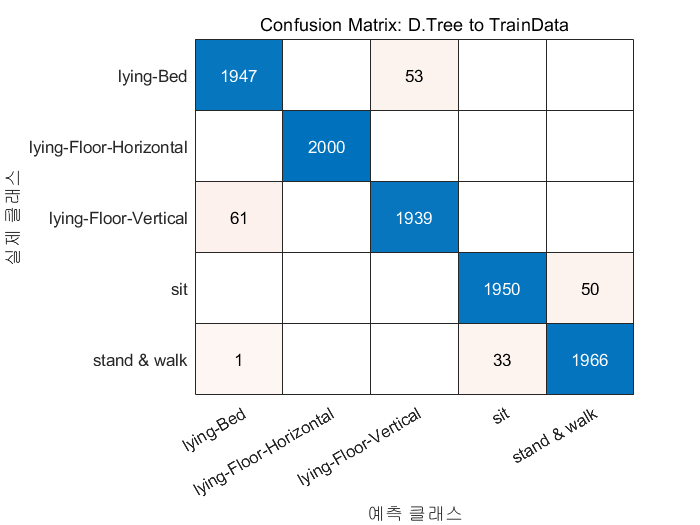

[Tree_Mdl, Tree_Train_Loss, ~] = ML_TreeTrain(TrainData_Table, TrainData_Label_Table);

**ML - Ensemble Method (Random Forest + Bagging)**

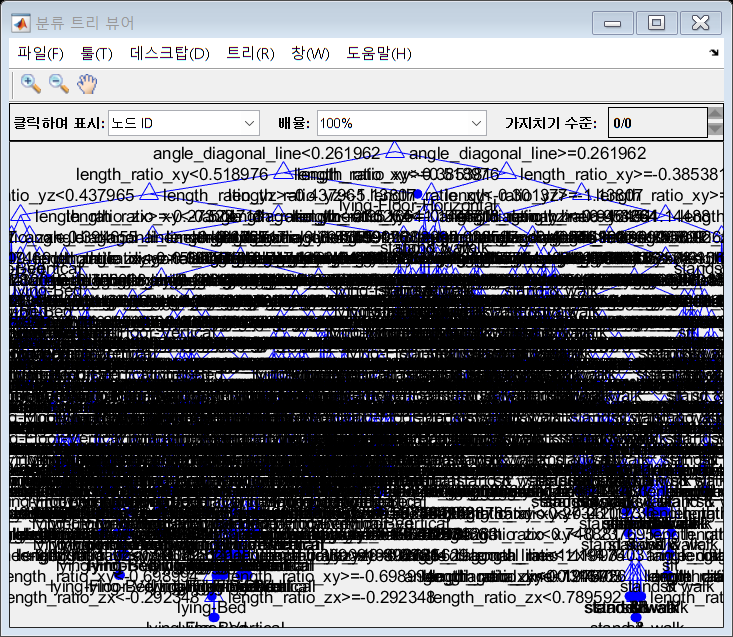

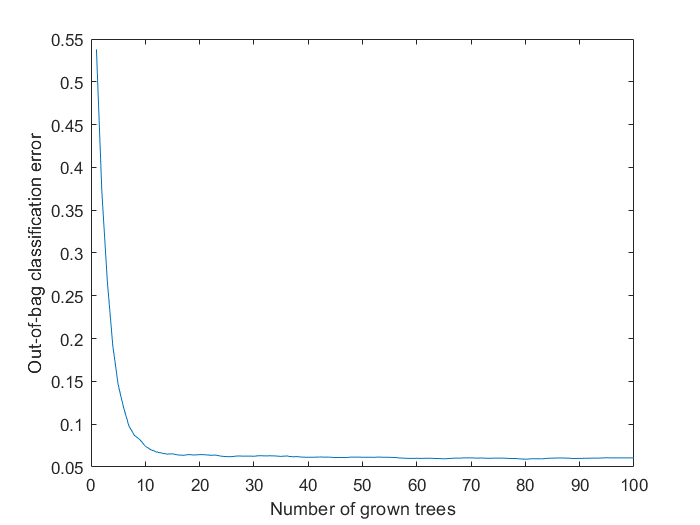

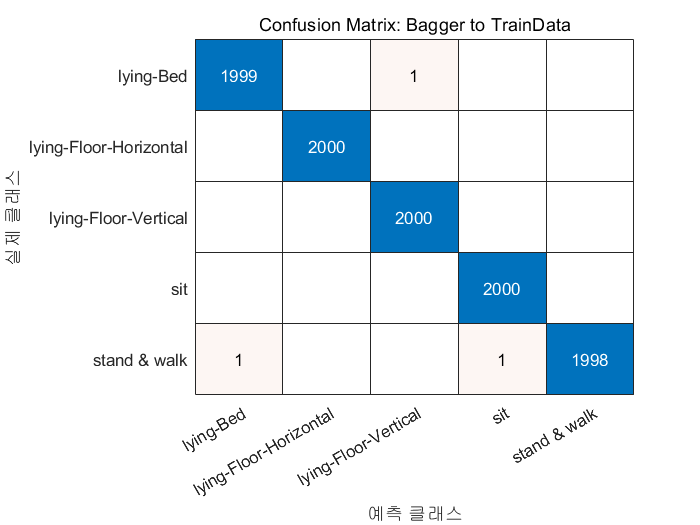

Bagger_Mdl =   TreeBagger
100개 배깅 결정 트리를 사용한 앙상블:
                    Training X:            [10000x4]
                    Training Y:            [10000x1]
                        Method:       classification
                 NumPredictors:                    4
         NumPredictorsToSample:                    2
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:     'lying-Bed' 'lying-Floor-Horizontal' 'lying-Floor-Vertical'           'sit'  'stand & walk'

  Properties, Methods


Ensemble_Train_Loss = 3.0000e-04

[Bagger_Mdl, Ensemble_Train_Loss, ~, ~, ~, ~] = Ensemble_TreeBaggerTrain(TrainData_Table, TrainData_Label_Table)

# **2-7.   Model Save**

save config/trained_Knn_Mdl Knn_Mdl
save config/trained_SVM_Mdl SVM_Mdl
save config/trained_Tree_Mdl Tree_Mdl
save config/trained_Bagger_Forest_Mdl Bagger_Mdl

# **3-1.   Load Test Data**

**Get ground truth label information.**

[matFiles, numFiles, mydata] = DataProcess_LoadData('testdata');

mydata_path = "../data/testdata/labeling_NTH214_1025_1930_CHOIHAEUN.mat"

mydata_path = "../data/testdata/labeling_NTH214_1025_2000_PARKJUEUN.mat"

# **3-2.   Data Pre-processing**

**Get names & Setting Base Variables**

mode = 5;

test_frame_info = DataProcess_DefineTestFrames(numFiles, matFiles, mode)

test_frame_info = 다음 필드를 포함한 1×2 struct 배열:
    name
    stand
    sit
    lying_1
    lying_2
    lying_3


**Get Labeled Frames**

LABEL_stand   = {};
LABEL_sit     = {};
LABEL_lying_1 = {};
LABEL_lying_2 = {};
LABEL_lying_3 = {};

for itr = 1 : numFiles
    [TMP_LABEL_stand, TMP_LABEL_sit, TMP_LABEL_lying_1, TMP_LABEL_lying_2, TMP_LABEL_lying_3] = DataProcess_GetLabel_5(mydata{itr,1}, test_frame_info(itr).stand, test_frame_info(itr).sit, test_frame_info(itr).lying_1, test_frame_info(itr).lying_2, test_frame_info(itr).lying_3);
    
    LABEL_stand   = [LABEL_stand   ; TMP_LABEL_stand];
    LABEL_sit     = [LABEL_sit     ; TMP_LABEL_sit];
    LABEL_lying_1 = [LABEL_lying_1 ; TMP_LABEL_lying_1];
    LABEL_lying_2 = [LABEL_lying_2 ; TMP_LABEL_lying_2];
    LABEL_lying_3 = [LABEL_lying_3 ; TMP_LABEL_lying_3];
end

**Check missing and outliers**

[no_stand_label_idx,   double_stand_label_idx,   num_of_standing] = DataProcess_DataCheck(LABEL_stand);
[no_sit_label_idx,     double_sit_label_idx,     num_of_sitting] = DataProcess_DataCheck(LABEL_sit);
[no_lying_1_label_idx, double_lying_1_label_idx, num_of_lying_1] = DataProcess_DataCheck(LABEL_lying_1);
[no_lying_2_label_idx, double_lying_2_label_idx, num_of_lying_2] = DataProcess_DataCheck(LABEL_lying_2);
[no_lying_3_label_idx, double_lying_3_label_idx, num_of_lying_3] = DataProcess_DataCheck(LABEL_lying_3);

# **3-3.   Feature Extraction**

**Get Bbox Coordinates**

stand_bboxes_coordinates   = DataProcess_BboxesExtraction(num_of_standing, LABEL_stand);
sit_bboxes_coordinates     = DataProcess_BboxesExtraction(num_of_sitting, LABEL_sit);
lying_1_bboxes_coordinates = DataProcess_BboxesExtraction(num_of_lying_1, LABEL_lying_1);
lying_2_bboxes_coordinates = DataProcess_BboxesExtraction(num_of_lying_2, LABEL_lying_2);
lying_3_bboxes_coordinates = DataProcess_BboxesExtraction(num_of_lying_3, LABEL_lying_3);

**Feature Extraction**

stand_feature_table   = DataProcess_FeatureExtraction(stand_bboxes_coordinates);
sit_feature_table     = DataProcess_FeatureExtraction(sit_bboxes_coordinates);
lying_1_feature_table = DataProcess_FeatureExtraction(lying_1_bboxes_coordinates);
lying_2_feature_table = DataProcess_FeatureExtraction(lying_2_bboxes_coordinates);
lying_3_feature_table = DataProcess_FeatureExtraction(lying_3_bboxes_coordinates);

# **3-4.   Data Post-processing**

**Add ground truth label to feature table**

stand_feature_label_table   = DataProcess_AddLabel(stand_feature_table,   'stand & walk');
sit_feature_label_table     = DataProcess_AddLabel(sit_feature_table,     'sit');
lying_1_feature_label_table = DataProcess_AddLabel(lying_1_feature_table, 'lying-Bed');
lying_2_feature_label_table = DataProcess_AddLabel(lying_2_feature_table, 'lying-Floor-Vertical');
lying_3_feature_label_table = DataProcess_AddLabel(lying_3_feature_table, 'lying-Floor-Horizontal');

**Define train data table (this table goes to ML)**

column_size = size(stand_feature_label_table, 2);

TestData_Table = [stand_feature_label_table(:,1:column_size-1) ; sit_feature_label_table(:,1:column_size-1) ; lying_1_feature_label_table(:,1:column_size-1) ; lying_2_feature_label_table(:,1:column_size-1) ; lying_3_feature_label_table(:,1:column_size-1)]

TestData_Table = 2000×4 table
    length_ratio_xy    length_ratio_yz    length_ratio_zx    angle_diagonal_line
    _______________    _______________    _______________    ___________________

        0.92032            0.51441            2.1123               55.043       
        0.90757            0.51729              2.13               55.063       
        0.89516            0.52013            2.1478               55.082       
        0.88309            0.52292            2.1655               55.099       
        0.84876            0.52981            2.2238               55.204       
        0.81469            0.53682            2.2865                 55.3       
        0.78085            0.54397            2.3543               55.388       
        0.85708            0.52026            2.2426               55.581       
        0.94064            0.49653            2.1411               55.718       
         1.0327            0.47279            2.0482               55.799     

TestData_Label_Table = [stand_feature_label_table(:,column_size) ; sit_feature_label_table(:,column_size) ; lying_1_feature_label_table(:,column_size) ; lying_2_feature_label_table(:,column_size) ; lying_3_feature_label_table(:,column_size)]

TestData_Label_Table = 2000×1 table
        label     
    ______________

    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"
    "stand & walk"


# **3-5.   Data Normalizaiton**

**method(1)**

Apply Data Normalization.

TestData_Table = normalize(TestData_Table)

TestData_Table = 2000×4 table
    length_ratio_xy    length_ratio_yz    length_ratio_zx    angle_diagonal_line
    _______________    _______________    _______________    ___________________

        -0.20816           -1.1858            0.54855               1.0385      
        -0.22164           -1.1791            0.56936               1.0398      
        -0.23474           -1.1724            0.59017                1.041      
         -0.2475           -1.1659            0.61098                1.042      
        -0.28376           -1.1497            0.67939               1.0486      
        -0.31976           -1.1332            0.75301               1.0547      
        -0.35551           -1.1165            0.83246               1.0601      
        -0.27497           -1.1721            0.70148               1.0723      
        -0.18669           -1.2278            0.58229               1.0809      
       -0.089485           -1.2835            0.47337               1.0859    

**method(2)**

Change Data Size by Apply Degree to Radian.

% TestData_array       = table2array(TestData_Table);
% TestData_array(:,4)  = TestData_array(:,4)*pi/180;
% FeatureColumnIndex   = ["length_ratio_xy", "length_ratio_yz", "length_ratio_zx", "angle_diagonal_line"];
% TestData_Table       = array2table(TestData_array, 'VariableNames',string(FeatureColumnIndex))

# **3-6.   Test Pretrained Model**

Knn                     = load('config/20221201_label_5/trained_Knn_Mdl.mat');
SVM                     = load('config/20221201_label_5/trained_SVM_Mdl.mat');
Decision_Tree           = load('config/20221201_label_5/trained_Tree_Mdl.mat');
Ensemble_Bagging_Forest = load('config/20221201_label_5/trained_Bagger_Forest_Mdl.mat');

**ML - KNN**

Test_Loss = 0.2765

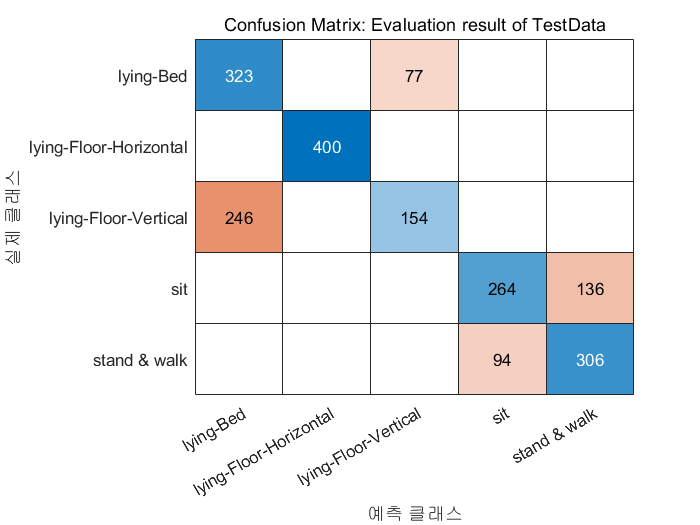

[Knn_Test_Loss, cm_knn] = ML_TEST(Knn.Knn_Mdl, TestData_Table, TestData_Label_Table);

**ML - SVM**

Test_Loss = 0.2485

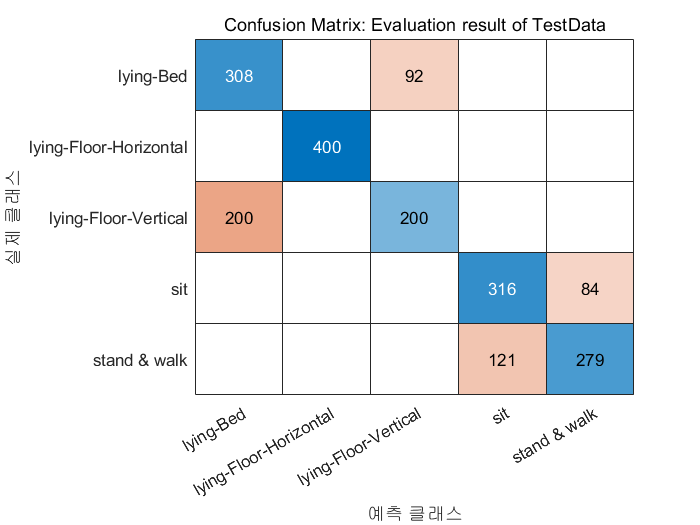

[SVM_Test_Loss, cm_svm] = ML_TEST(SVM.SVM_Mdl, TestData_Table, TestData_Label_Table);

**ML - Tree**

Test_Loss = 0.2595

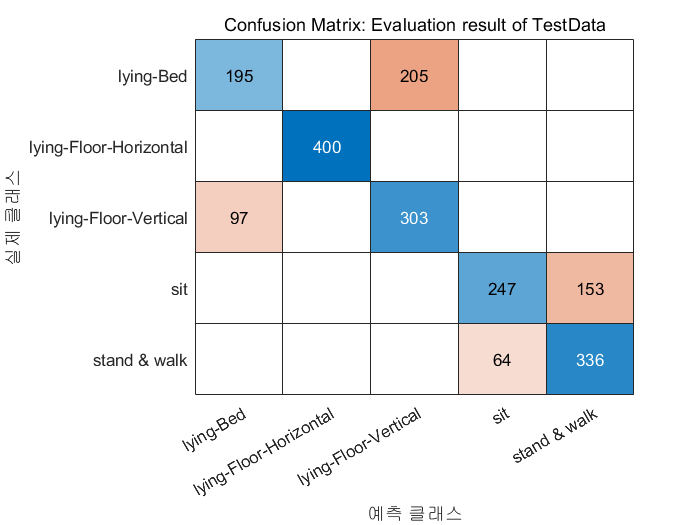

[Tree_Test_Loss, cm_tree] = ML_TEST(Decision_Tree.Tree_Mdl, TestData_Table, TestData_Label_Table);

**ML - Ensemble Method (Random Forest + Bagging)**

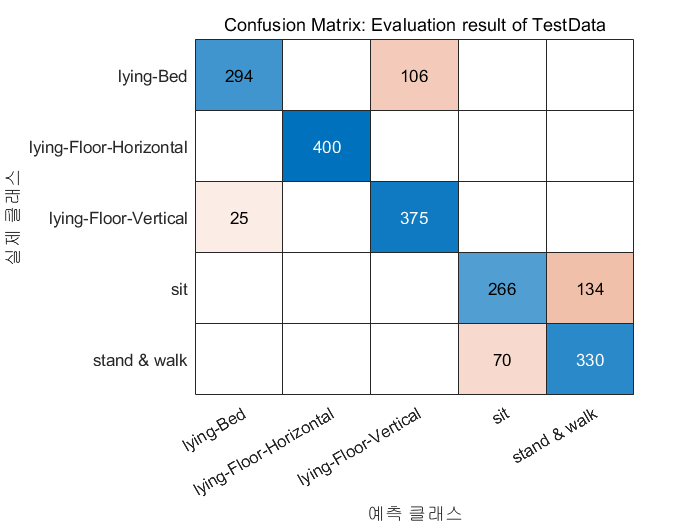

Bagger_Test_Loss = 0.1675

cm_ensemble =   ConfusionMatrixChart (Confusion Matrix: Evaluation result of TestData) - 속성 있음:

    NormalizedValues: [5×5 double]
         ClassLabels: [5×1 categorical]

  모든 속성 표시


[Bagger_Test_Loss, cm_ensemble] = Ensemble_TEST(Ensemble_Bagging_Forest.Bagger_Mdl, TestData_Table, TestData_Label_Table)

# **3-7.   Evaluation**

**F1 Score Evaluation**

    다중 분류 문제에서의 F1 Score 구하기 : Click [Here](https://nittaku.tistory.com/295)

**    TP =** 실제 양성(불량, 비정상), 예측도 양성(불량, 비정상)으로 한 Data

**    TN = **실제 음성(정상), 예측도 음성(정상)으로 한 Data

**    FP =** 실제로는 음성(정상), 예측은 반대로 양성(불량, 비정상)으로 한 Data

**    FN =** 실제로는 양성(불량, 비정상), 예측은 반대로 음성(정상)으로 한 Data

**KNN Evaluation**

[Table, sub_Table] = Evaluation_ConfMat(cm_knn)

Table = 4×1 table
                 Evaluation Result
                 _________________

    Accuracy           0.7235     
    Precision         0.73281     
    Recall             0.7235     
    F1_score          0.71564     


sub_Table = 5×3 table
    Precision by Class    Recall by Class       F1scores by Class 
    __________________    __________________    __________________

         0.56766                0.8075               0.66667      
               1                     1                     1      
         0.66667                 0.385               0.48811      
         0.73743                  0.66               0.69657      
         0.69231                 0.765               0.72684      


**SVM Evaluation**

[Table, sub_Table] = Evaluation_ConfMat(cm_svm)

Table = 4×1 table
                 Evaluation Result
                 _________________

    Accuracy           0.7515     
    Precision         0.75659     
    Recall             0.7515     
    F1_score          0.74857     


sub_Table = 5×3 table
    Precision by Class    Recall by Class       F1scores by Class 
    __________________    __________________    __________________

          0.6063                  0.77               0.67841      
               1                     1                     1      
         0.68493                   0.5               0.57803      
         0.72311                  0.79               0.75508      
          0.7686                0.6975               0.73132      


**Tree Evaluation**

[Table, sub_Table] = Evaluation_ConfMat(cm_tree)

Table = 4×1 table
                 Evaluation Result
                 _________________

    Accuracy           0.7405     
    Precision         0.74912     
    Recall             0.7405     
    F1_score          0.73634     


sub_Table = 5×3 table
    Precision by Class    Recall by Class       F1scores by Class 
    __________________    __________________    __________________

         0.66781                0.4875               0.56358      
               1                     1                     1      
         0.59646                0.7575                0.6674      
         0.79421                0.6175                0.6948      
         0.68712                  0.84               0.75591      


**Ensemble Evaluation**

[Table, sub_Table] = Evaluation_ConfMat(cm_ensemble)

Table = 4×1 table
                 Evaluation Result
                 _________________

    Accuracy           0.8325     
    Precision         0.84083     
    Recall             0.8325     
    F1_score          0.83116     


sub_Table = 5×3 table
    Precision by Class    Recall by Class       F1scores by Class 
    __________________    __________________    __________________

         0.92163                 0.735                0.8178      
               1                     1                     1      
         0.77963                0.9375               0.85131      
         0.79167                 0.665               0.72283      
         0.71121                 0.825               0.76389      


# **3-8.   Moving Median Filter**

***(NEW)***

**Before Moving Median Filter**

% [~, cm_ensemble] = Ensemble_TEST(Ensemble_Bagging_Forest.Bagger_Mdl, TestData_Table, TestData_Label_Table)
% [Table, sub_Table] = Evaluation_ConfMat(cm_ensemble)

**Non-Overlapping Moving Median Filter**

% [loss, cm_filter_1] = Filter_MovingMedian(TestData_Table, TestData_Label_Table, Ensemble_Bagging_Forest.Bagger_Mdl, 5, "X", 5)
% [Table, sub_Table] = Evaluation_ConfMat(cm_filter_1)

**Overlapping Moving Median Filter**

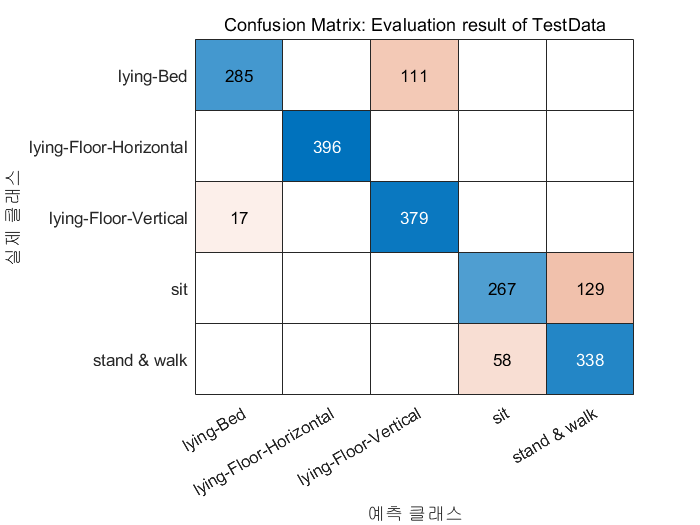

loss = 0.1591

cm_filter_2 =   ConfusionMatrixChart (Confusion Matrix: Evaluation result of TestData) - 속성 있음:

    NormalizedValues: [5×5 double]
         ClassLabels: [5×1 categorical]

  모든 속성 표시


[loss, cm_filter_2] = Filter_MovingMedian(TestData_Table, TestData_Label_Table, Ensemble_Bagging_Forest.Bagger_Mdl, 5, "O", 5)

[Table, sub_Table] = Evaluation_ConfMat(cm_filter_2)

Table = 4×1 table
                 Evaluation Result
                 _________________

    Accuracy          0.84091     
    Precision          0.8525     
    Recall            0.84091     
    F1_score          0.83922     


sub_Table = 5×3 table
    Precision by Class    Recall by Class       F1scores by Class 
    __________________    __________________    __________________

         0.94371                0.7197               0.81662      
               1                     1                     1      
         0.77347               0.95707               0.85553      
         0.82154               0.67424               0.74064      
         0.72377               0.85354               0.78331      


**Overlapping Moving Median Filter**

% [loss, cm_filter_2] = Filter_MovingMedian(TestData_Table, TestData_Label_Table, Ensemble_Bagging_Forest.Bagger_Mdl, 7, "O", 5)
% [Table, sub_Table] = Evaluation_ConfMat(cm_filter_2)

**Overlapping Moving Median Filter**

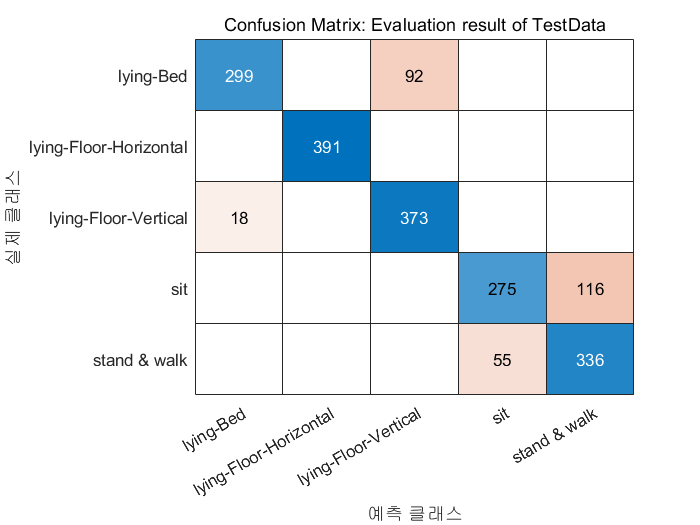

loss = 0.1437

cm_filter_2 =   ConfusionMatrixChart (Confusion Matrix: Evaluation result of TestData) - 속성 있음:

    NormalizedValues: [5×5 double]
         ClassLabels: [5×1 categorical]

  모든 속성 표시


[loss, cm_filter_2] = Filter_MovingMedian(TestData_Table, TestData_Label_Table, Ensemble_Bagging_Forest.Bagger_Mdl, 10, "O", 5)

[Table, sub_Table] = Evaluation_ConfMat(cm_filter_2)

Table = 4×1 table
                 Evaluation Result
                 _________________

    Accuracy          0.85627     
    Precision         0.86441     
    Recall            0.85627     
    F1_score          0.85522     


sub_Table = 5×3 table
    Precision by Class    Recall by Class       F1scores by Class 
    __________________    __________________    __________________

         0.94322               0.76471               0.84463      
               1                     1                     1      
         0.80215               0.95396                0.8715      
         0.83333               0.70332               0.76283      
         0.74336               0.85934               0.79715      


# **4. PCA**

### Apply PCA

rng(0)

TrainData_Table_Array = table2array(TrainData_Table);
[PCA_coeff, PCA_data, ~, ~, PCA_explained, PCA_Center] = pca(TrainData_Table_Array);

% Returns Explained, the percentage of the total variance explained by each principal component
PCA_explained

PCA_explained =    72.6331
   25.6450
    1.3858
    0.3361


# **5.   Result & Conclusion**